# RVC2: Chapter 6

format compact
close all
clear
clc

##  6.1 Dead reckoning

## 6.1.1 Modeling the vehicle

V = diag([0.02, 0.5*pi/180].^2);

veh = Bicycle('covar', V)

veh = 
Bicycle object                      
  L=1, steer.max=0.5, accel.max=Inf 
  Superclass: Vehicle               
    max speed=1, dT=0.1, nhist=0    
    V=(0.0004, 7.61544e-05)         
    configuration: x=0, y=0, theta=0



randinit
odo = veh.step(1, 0.3)

odo =     0.1108    0.0469



veh.x'

ans =     0.1000         0    0.0309



veh.f([0 0 0], odo)

ans =     0.1106    0.0052    0.0469


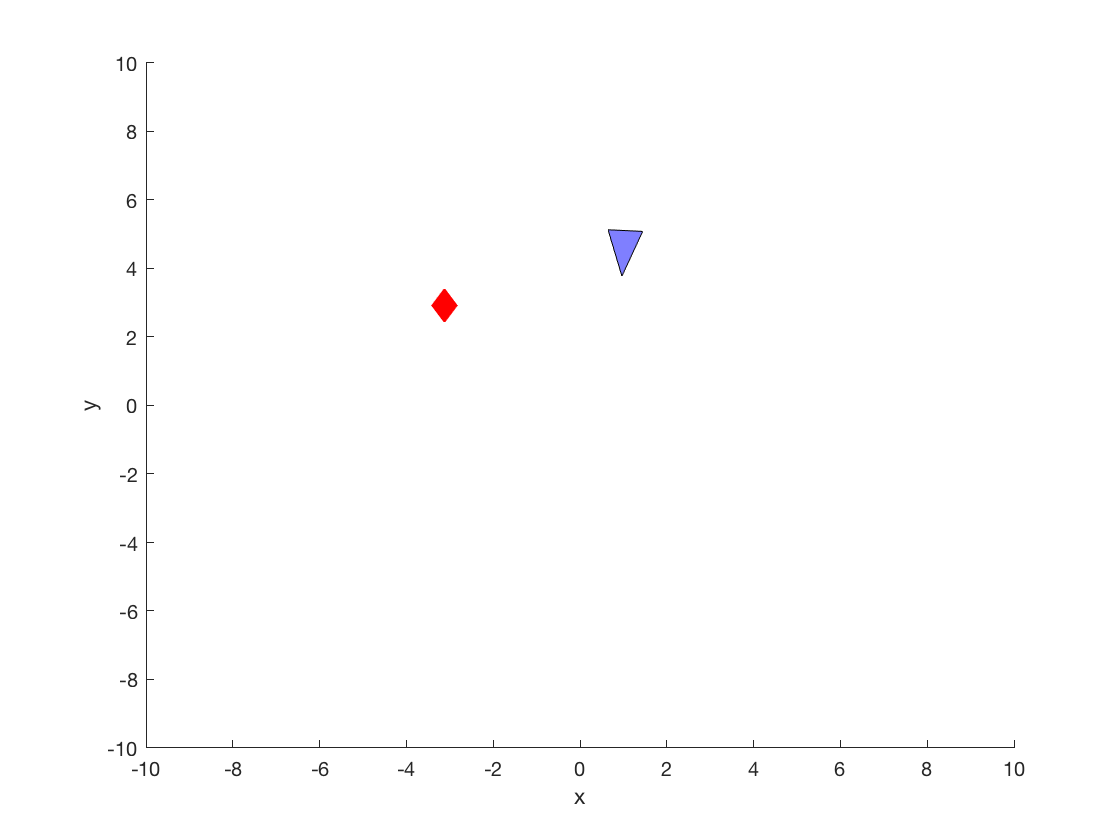

ans =     0.1000         0    0.0309
    0.2000    0.0031   -0.0237
    0.2999    0.0007   -0.0783
    0.3996   -0.0071   -0.1330
    0.4987   -0.0204   -0.1876
    0.5970   -0.0390   -0.2422
    0.6941   -0.0630   -0.2968
    0.7897   -0.0922   -0.3515
    0.8836   -0.1267   -0.4061
    0.9754   -0.1662   -0.4607



veh.add_driver( RandomPath(10) )
veh.run()

##  6.1.2  Estimating pose

veh.Fx( [0,0,0], [0.5, 0.1] )

ans =     1.0000         0   -0.0499
         0    1.0000    0.4975
         0         0    1.0000



P0 = diag([0.005, 0.005, 0.001].^2);

ekf = EKF(veh, V, P0);

randinit
ekf.run(1000);


clf
veh.plot_xy()

hold on
ekf.plot_xy('r')

P700 = ekf.history(700).P

P700 =     1.8557    0.6276    0.2297
    0.6276    1.6959    0.2095
    0.2297    0.2095    0.0533



sqrt(P700(1,1))

ans = 1.3623

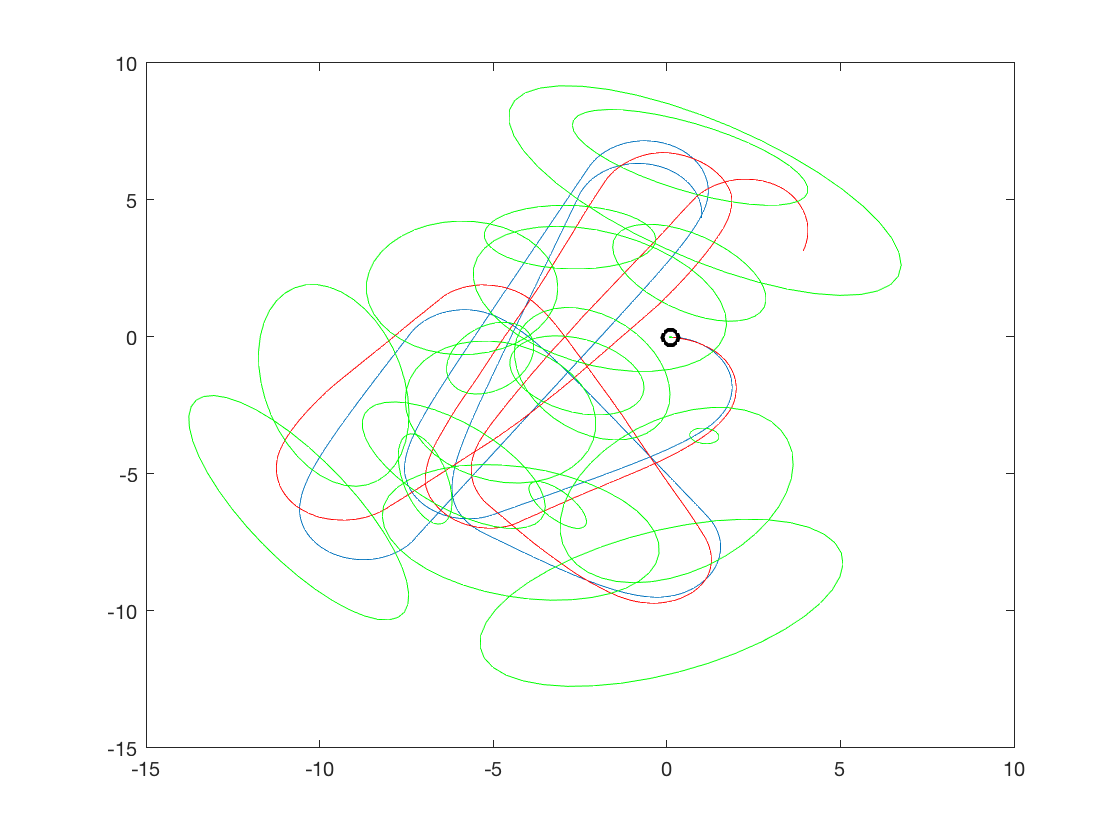


ekf.plot_ellipse('g')

##  6.2 Map-based localization

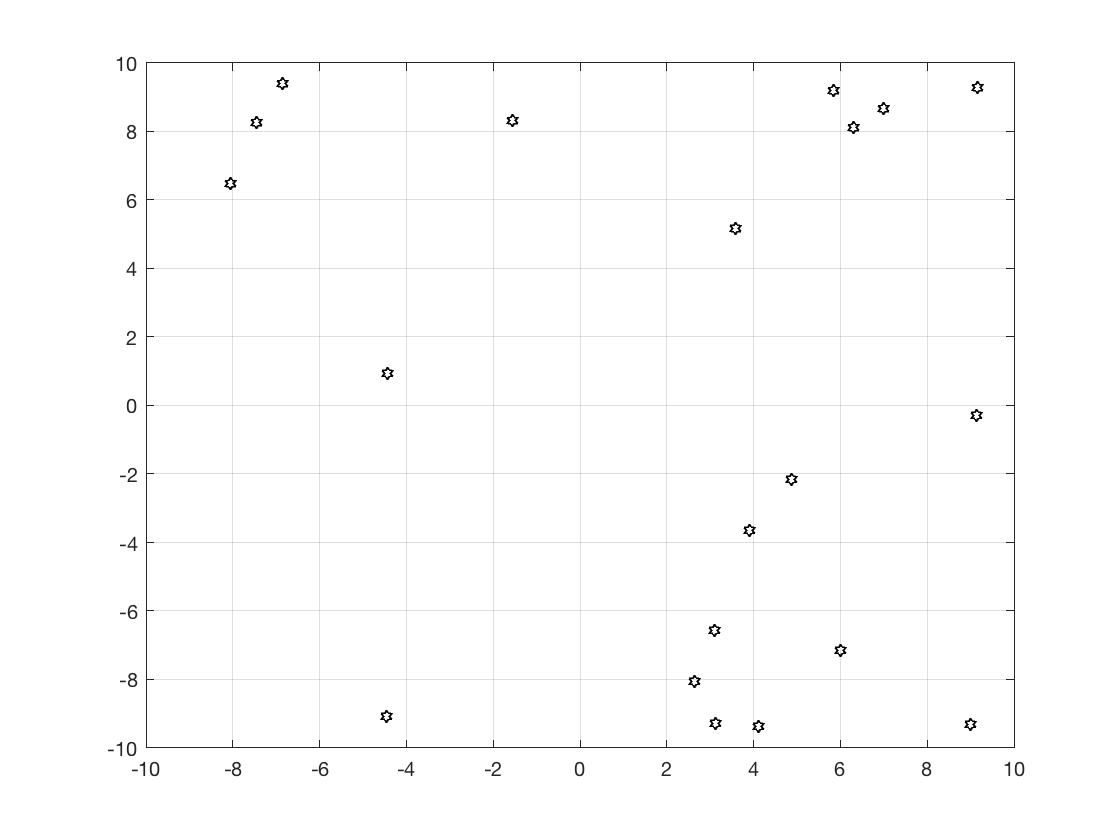

randinit
map = LandmarkMap(20, 10);

map.plot()


W = diag([0.1, 1*pi/180].^2);

sensor = RangeBearingSensor(veh, map, 'covar', W)

sensor = 
RangeBearingSensor sensor class:
LandmarkMap object              
  20 landmarks                  
  dimension 10.0                
W = [0.01 0;0 0.000305]         
interval 1 samples              




[z,i] = sensor.reading()

z =    14.6639
   -0.3076


i = 17


map.landmark(17)

ans =    -4.4615
   -9.0766


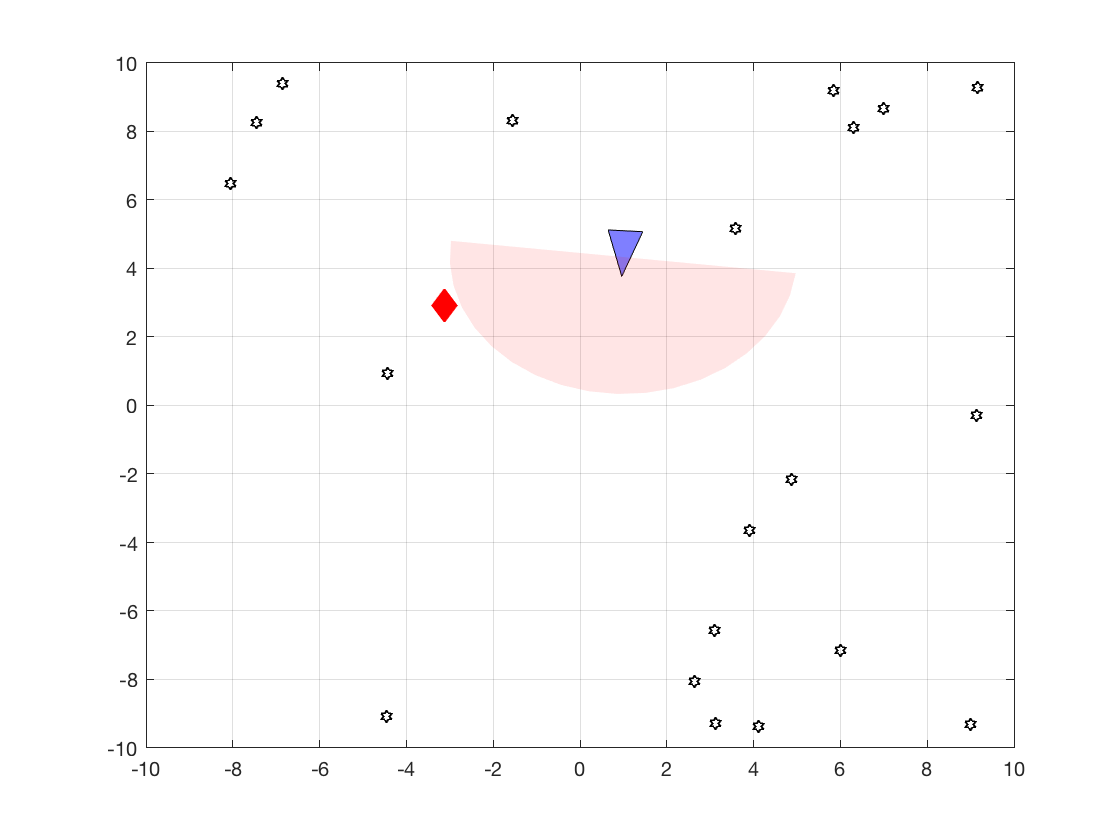


randinit
map = LandmarkMap(20);
veh = Bicycle('covar', V);
veh.add_driver( RandomPath(map.dim) );
sensor = RangeBearingSensor(veh, map, 'covar', W, 'angle', ...
[-pi/2 pi/2], 'range', 4, 'animate');
ekf = EKF(veh, V, P0, sensor, W, map);

ekf.run(1000);

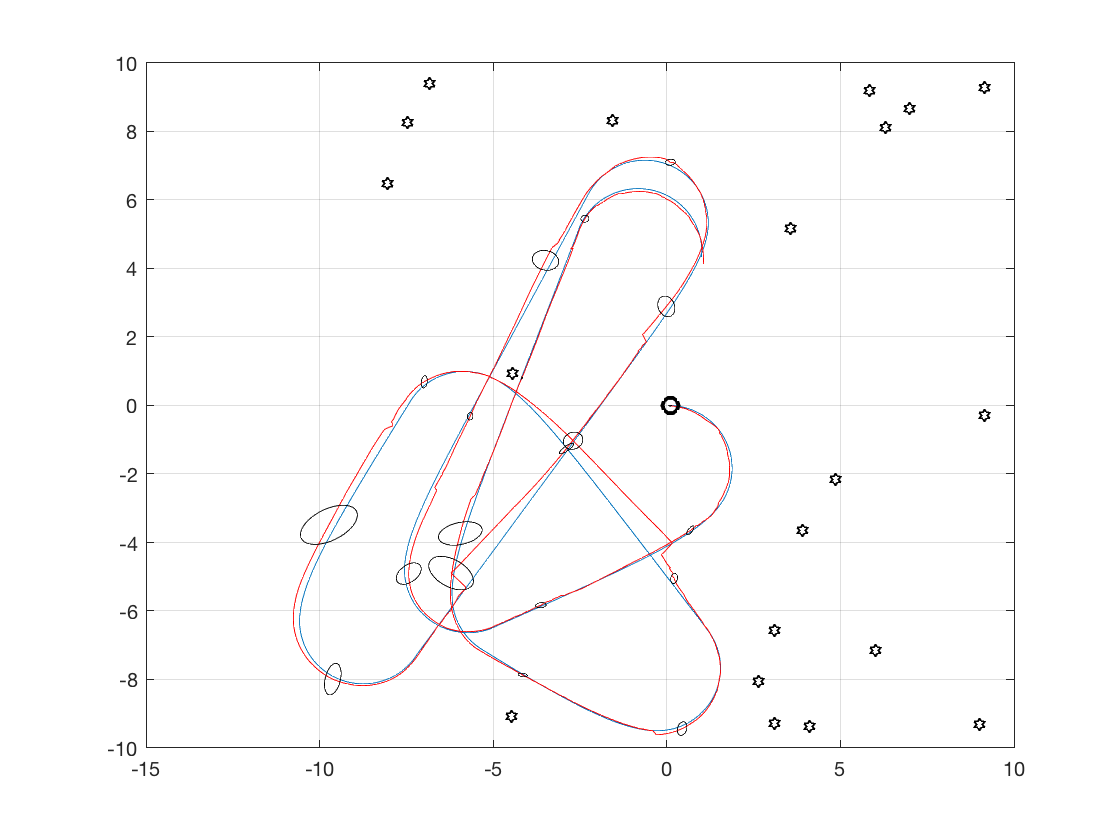

map.plot()
veh.plot_xy();
ekf.plot_xy('r');
ekf.plot_ellipse('k')

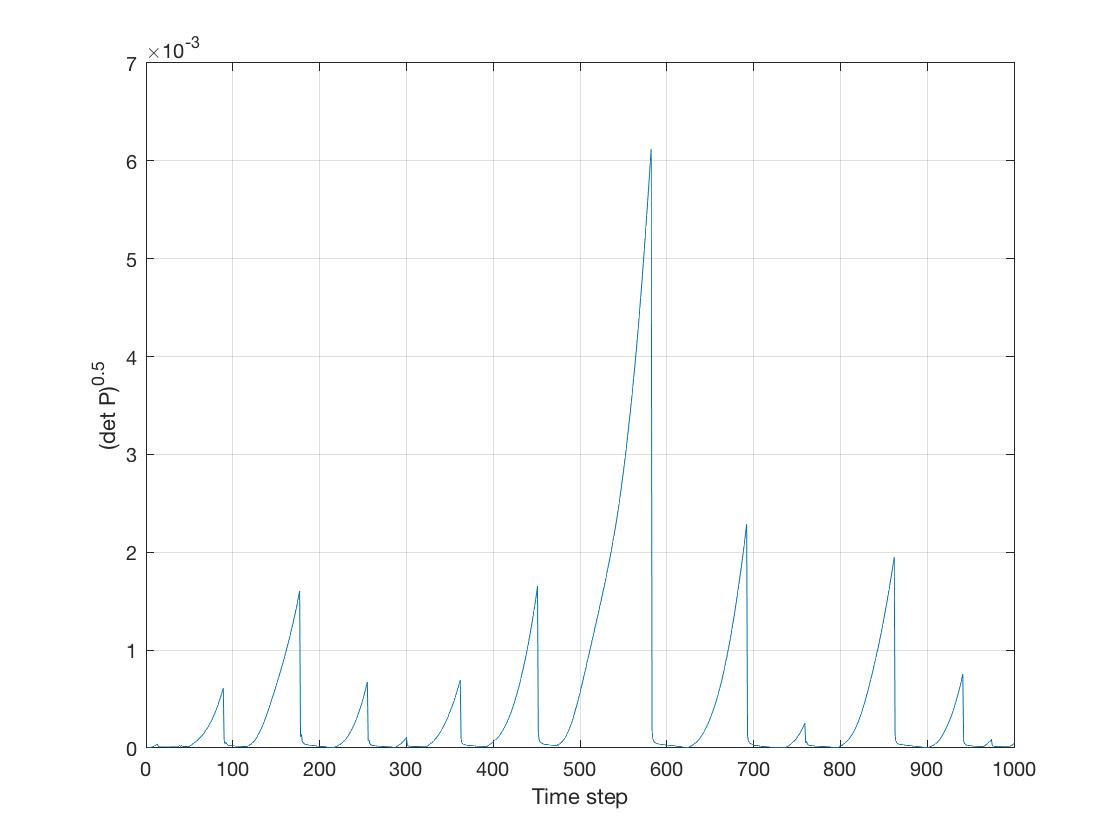


clf
ekf.plot_P()
xlabel('Time step'); ylabel('(det P)^{0.5}'); grid

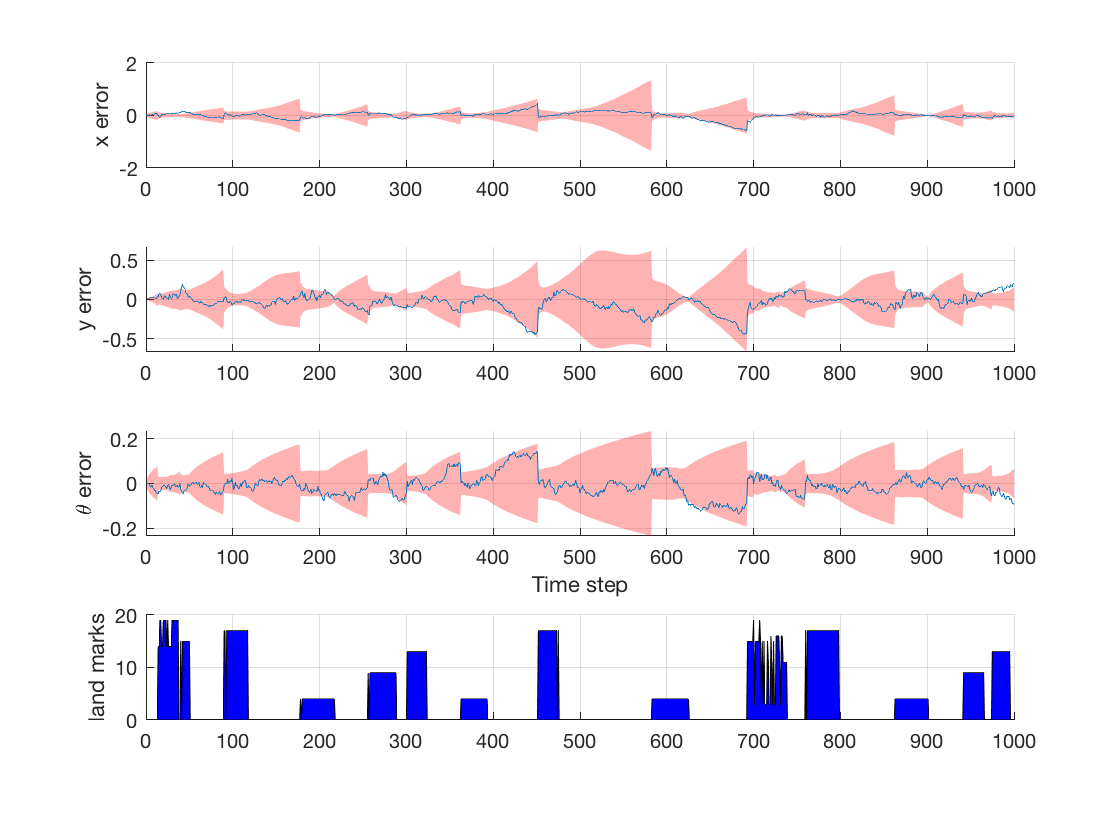


clf
ekf.plot_error('confidence', 0.95, 'nplots', 4)
plot_poly([1:1000; sensor.landmarklog], 'fill', 'b')
ylabel('land marks')
grid

##  6.3  Creating a map

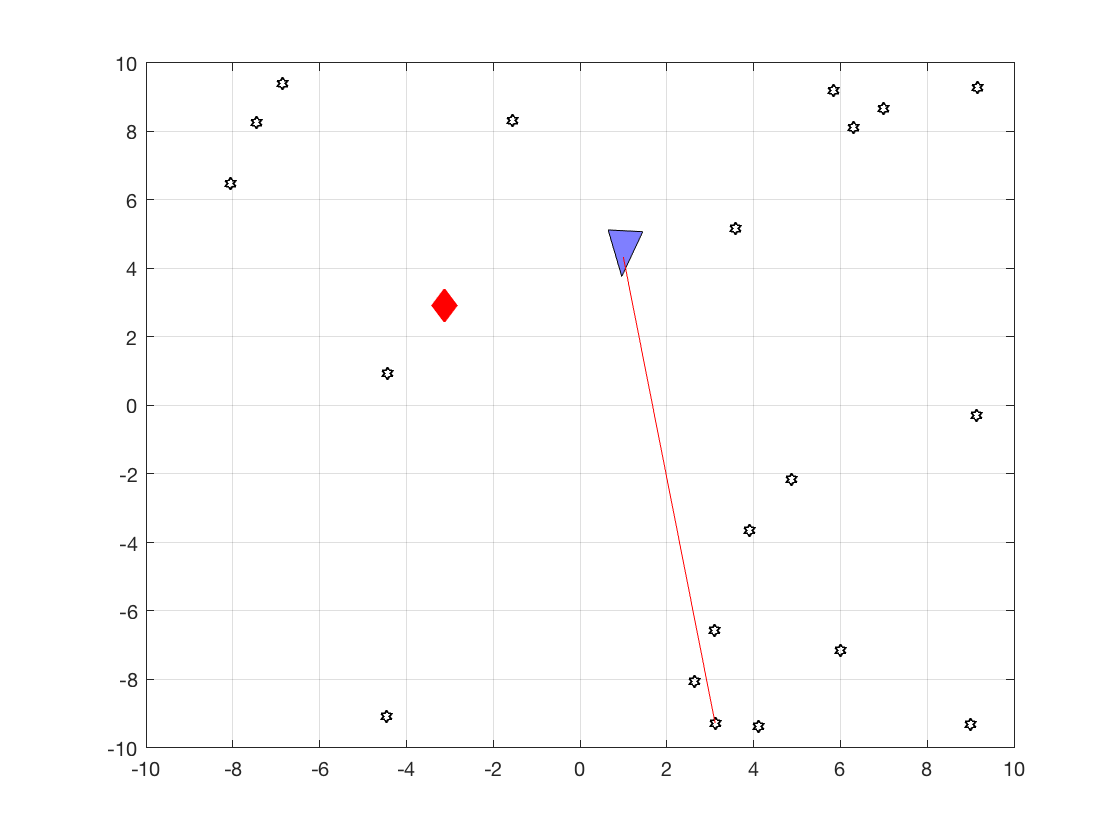

randinit
map = LandmarkMap(20);
veh = Bicycle(); % error free vehicle
veh.add_driver( RandomPath(map.dim) );
W = diag([0.1, 1*pi/180].^2);
sensor = RangeBearingSensor(veh, map, 'covar', W, 'animate');
ekf = EKF(veh, [], [], sensor, W, []);

ekf.run(1000);

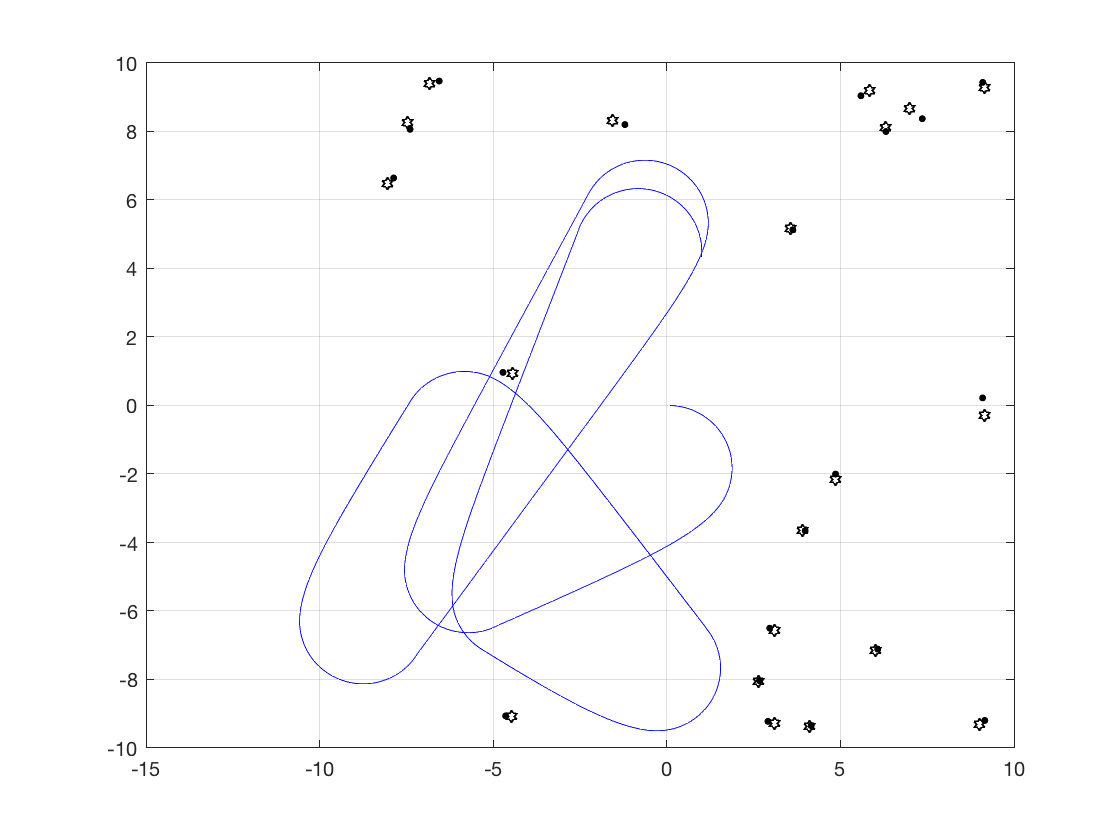


map.plot();
ekf.plot_map('g');
veh.plot_xy('b');



ekf.landmarks(:,6)

ans =     19
    71



ekf.x_est(19:20)'

ans =    -6.5552    9.4739



ekf.P_est(19:20,19:20)

ans = 	1.0e+-3 *

    0.3549    0.0480
    0.0480    0.1644


##  6.4  EKF SLAM

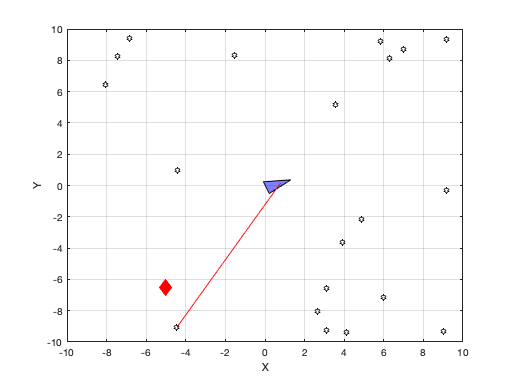

Unable to perform assignment because the left and right sides have a different number of elements.

Error in EKF/step (line 920)
                    x_est(3) = angdiff(x_est(3));

Error in EKF/run (line 415)
                ekf.step(opt);

randinit
P0 = diag([.01, .01, 0.005].^2);
map = LandmarkMap(20);
veh = Bicycle('covar', V);
veh.add_driver( RandomPath(map.dim) );
sensor = RangeBearingSensor(veh, map, 'covar', W, 'animate');
ekf = EKF(veh, V, P0, sensor, W, []);

ekf.run(1000);


map.plot();
ekf.plot_map('g');
ekf.plot_xy('r');
veh.plot_xy('b');


##  6.6 Pose-graph SLAM

syms x_i y_i theta_i x_j y_j theta_j x_m y_m theta_m assume real
xi_e = inv( SE2(x_m, y_m, theta_m) ) * inv( SE2(x_i, y_i, theta_i) ) * SE2(x_j, y_j, theta_j);
fk = simplify(xi_e.xyt);

jacobian ( fk, [x_i y_i theta_i] );
Ai = simplify (ans)

$$Ai = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & -\sin\left(\theta_{i}+\theta_{m}\right) & y_{j}\,\cos\left(\theta_{i}+\theta_{m}\right)-y_{i}\,\cos\left(\theta_{i}+\theta_{m}\right)+x_{i}\,\sin\left(\theta_{i}+\theta_{m}\right)-x_{j}\,\sin\left(\theta_{i}+\theta_{m}\right)\\ \sin\left(\theta_{i}+\theta_{m}\right) & \sigma_{1} & x_{i}\,\cos\left(\theta_{i}+\theta_{m}\right)-x_{j}\,\cos\left(\theta_{i}+\theta_{m}\right)+y_{i}\,\sin\left(\theta_{i}+\theta_{m}\right)-y_{j}\,\sin\left(\theta_{i}+\theta_{m}\right)\\ 0 & 0 & -1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\cos\left(\theta_{i}+\theta_{m}\right) \end{array}$$


pg = PoseGraph('pg1.g2o')

loaded g2o format file: 4 nodes, 4 edges in 0.02 sec


pg =   PoseGraph with properties:

       graph: [1×1 PGraph]
       ngrid: []
      center: []
    cellsize: []

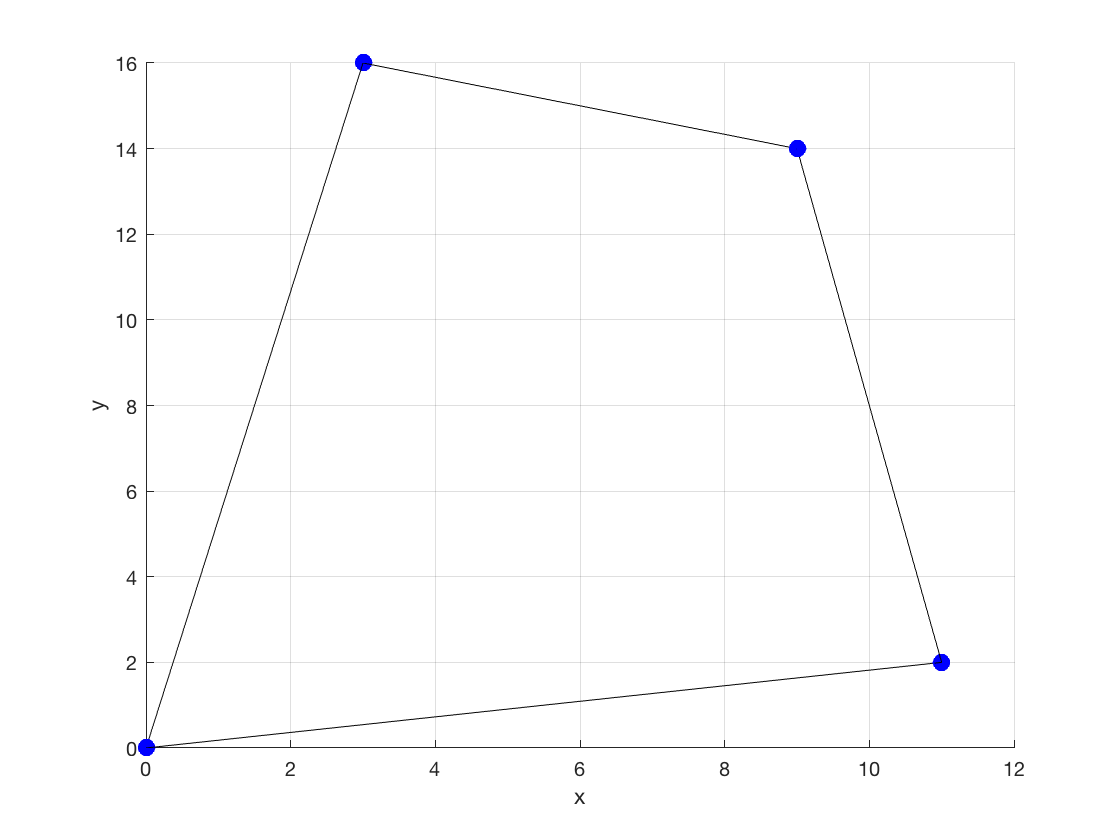


clf
pg.plot()

solving....done in 0.031 sec.  Total cost 316.88 


solving....done in 0.018 sec.  Total cost 47.2186 


solving....done in 0.0055 sec.  Total cost 41.8271 


solving....done in 0.0074 sec.  Total cost 0.566455 


solving....done in 0.0082 sec.  Total cost 0.00378236 


solving....done in 0.0039 sec.  Total cost 1.15234e-09 


solving....done in 0.0054 sec.  Total cost 3.14139e-11 


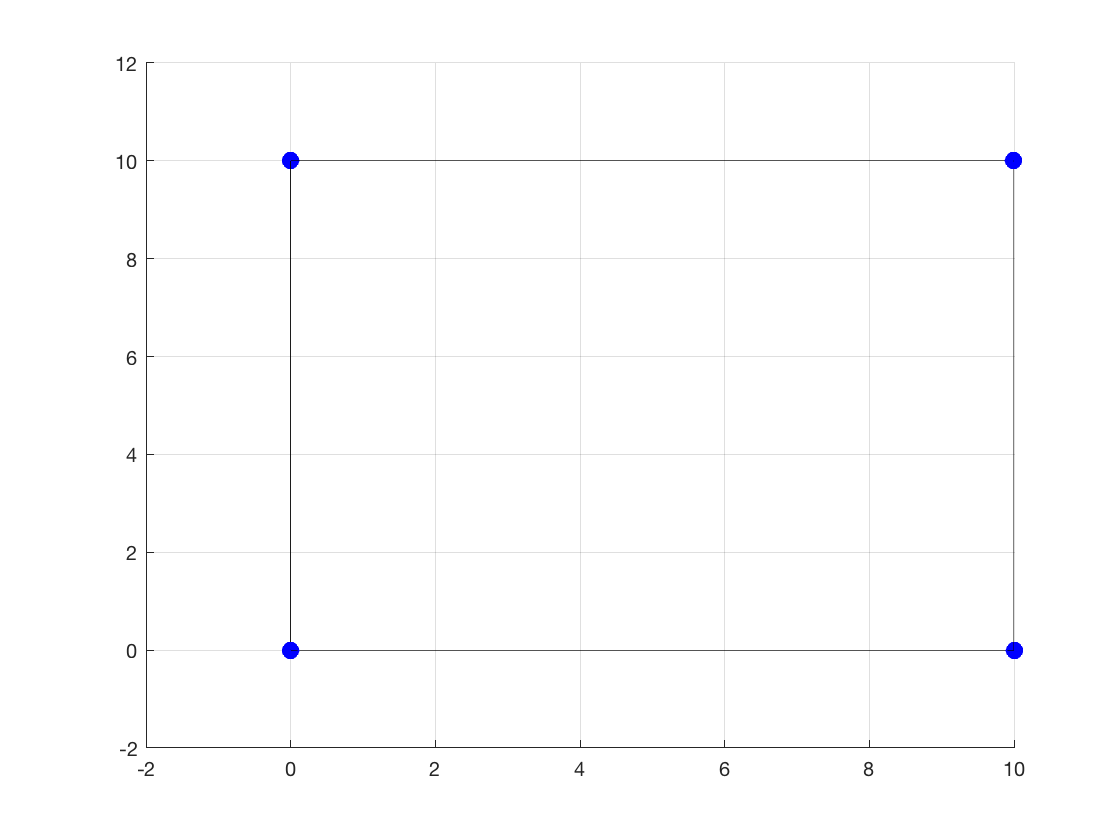

solving....done in 0.0039 sec.  Total cost 3.14139e-11 
ans = 
  3 dimensions
  4 vertices  
  4 edges     
  1 components



pg.optimize('animate')

pg = PoseGraph('killian-small.toro');

loaded TORO/LAGO format file: 1941 nodes, 3995 edges in 0.88 sec


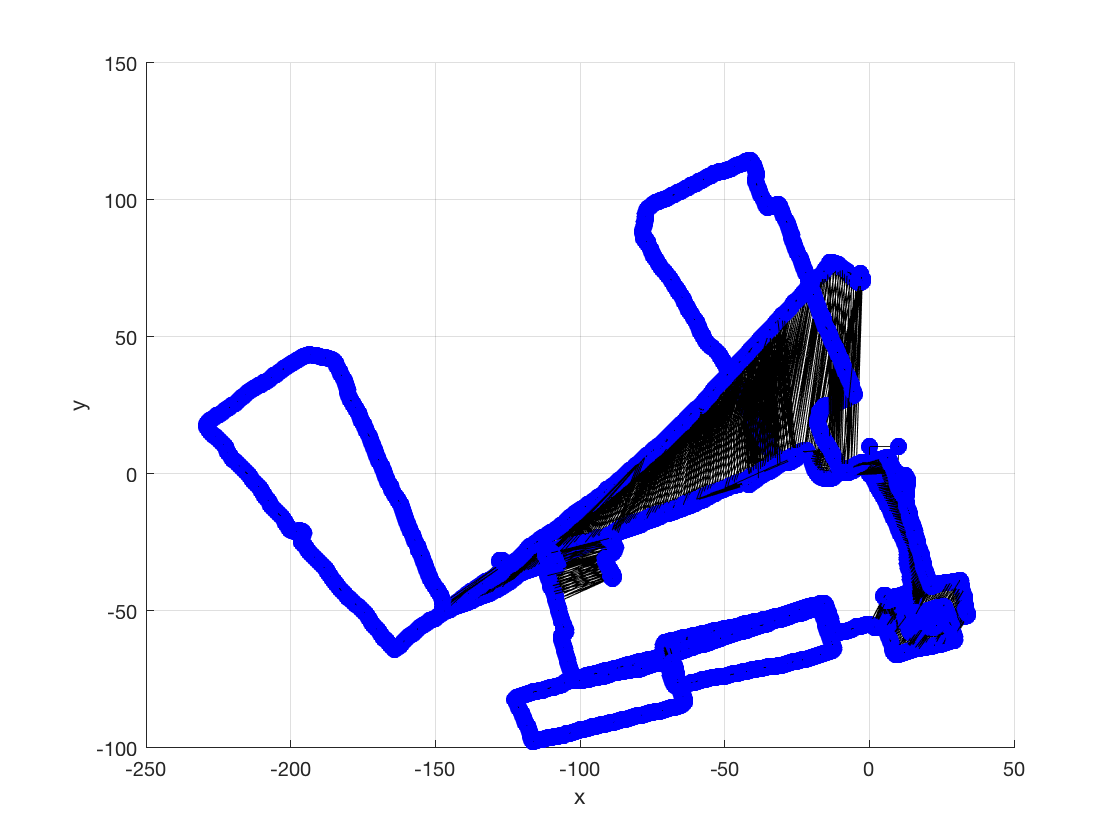


pg.plot()


pg.optimize()

solving....done in 1 sec.  Total cost 1.78135e+06 
solving....done in 0.86 sec.  Total cost 1.39949e+06 
solving....done in 0.77 sec.  Total cost 36.6777 
solving....done in 0.75 sec.  Total cost 5.44579 
solving....done in 0.78 sec.  Total cost 5.44565 
solving....done in 0.79 sec.  Total cost 5.44567 
ans = 
  3 dimensions 
  1941 vertices
  3995 edges   
  1 components 


## 6.7  Particle filter

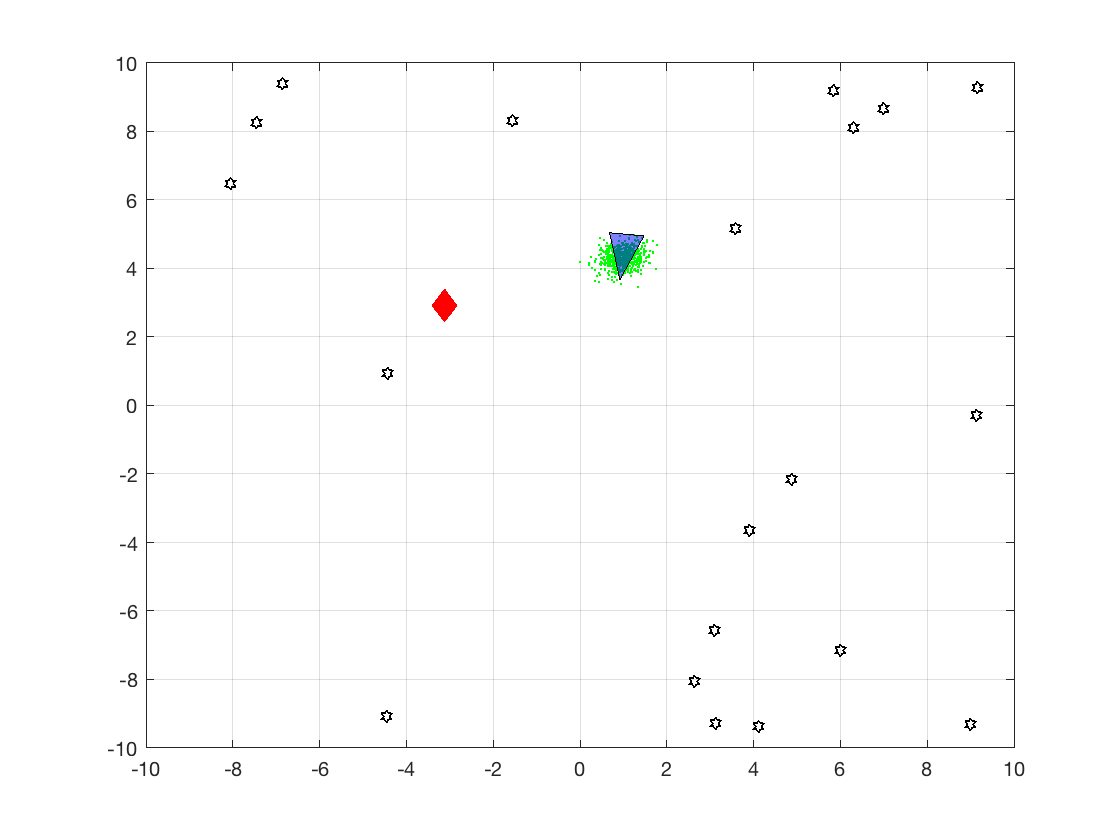

randinit
map = LandmarkMap(20);
W = diag([0.1, 1*pi/180].^2);
veh = Bicycle('covar', V);
veh.add_driver( RandomPath(10) );

V = diag([0.005, 0.5*pi/180].^2);
sensor = RangeBearingSensor(veh, map, 'covar', W);

Q = diag([0.1, 0.1, 1*pi/180]).^2;

L = diag([0.1 0.1]);

pf = ParticleFilter(veh, sensor, Q, L, 1000);

pf.run(1000);

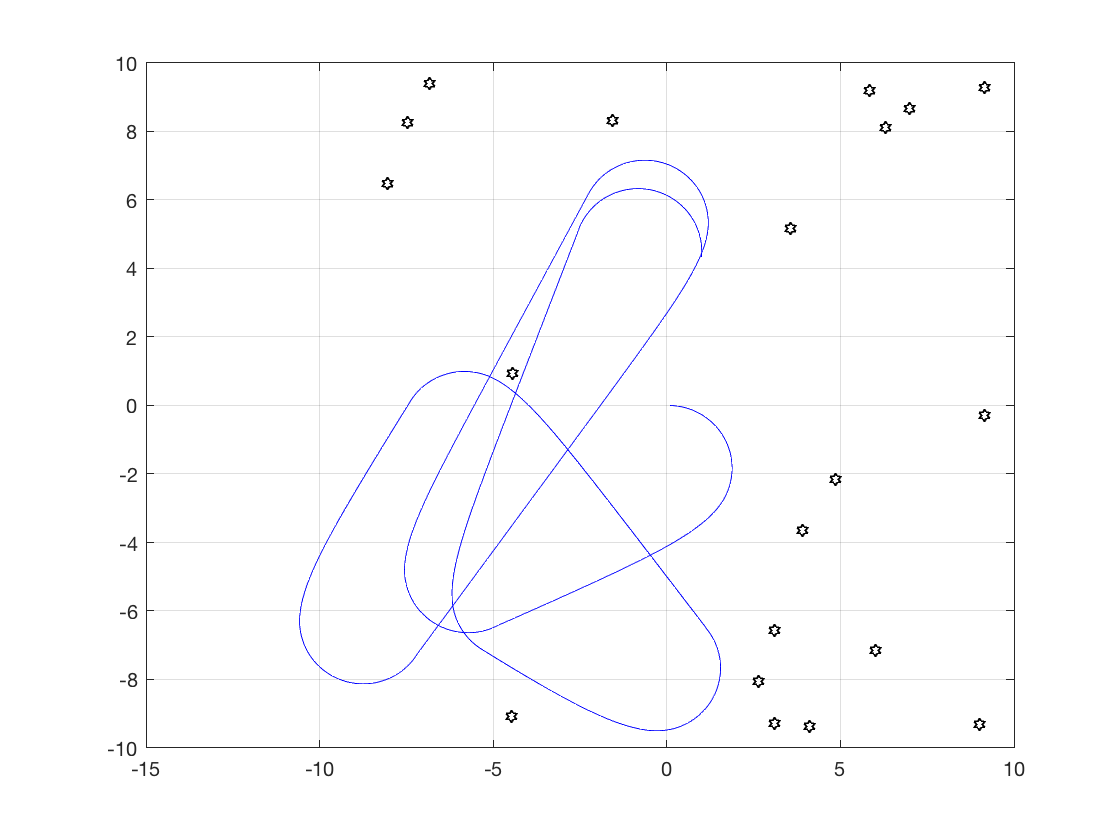


map.plot();
veh.plot_xy('b');

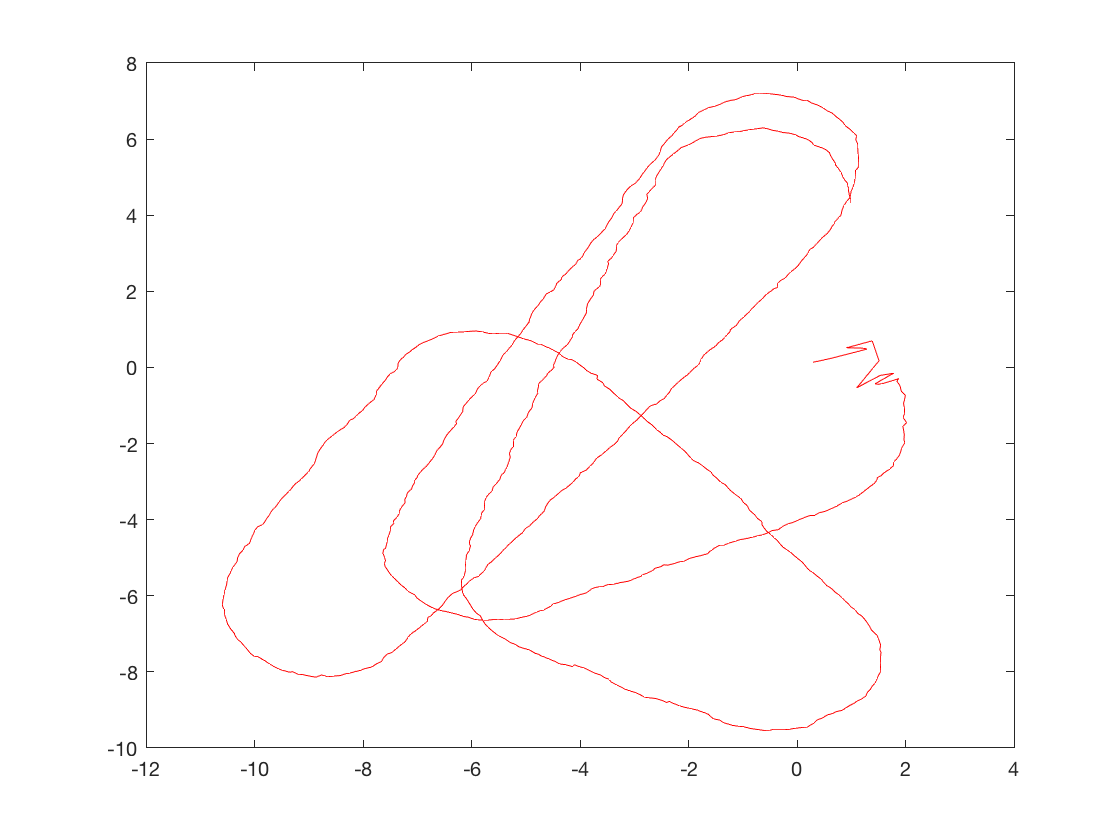


clf
pf.plot_xy('r');

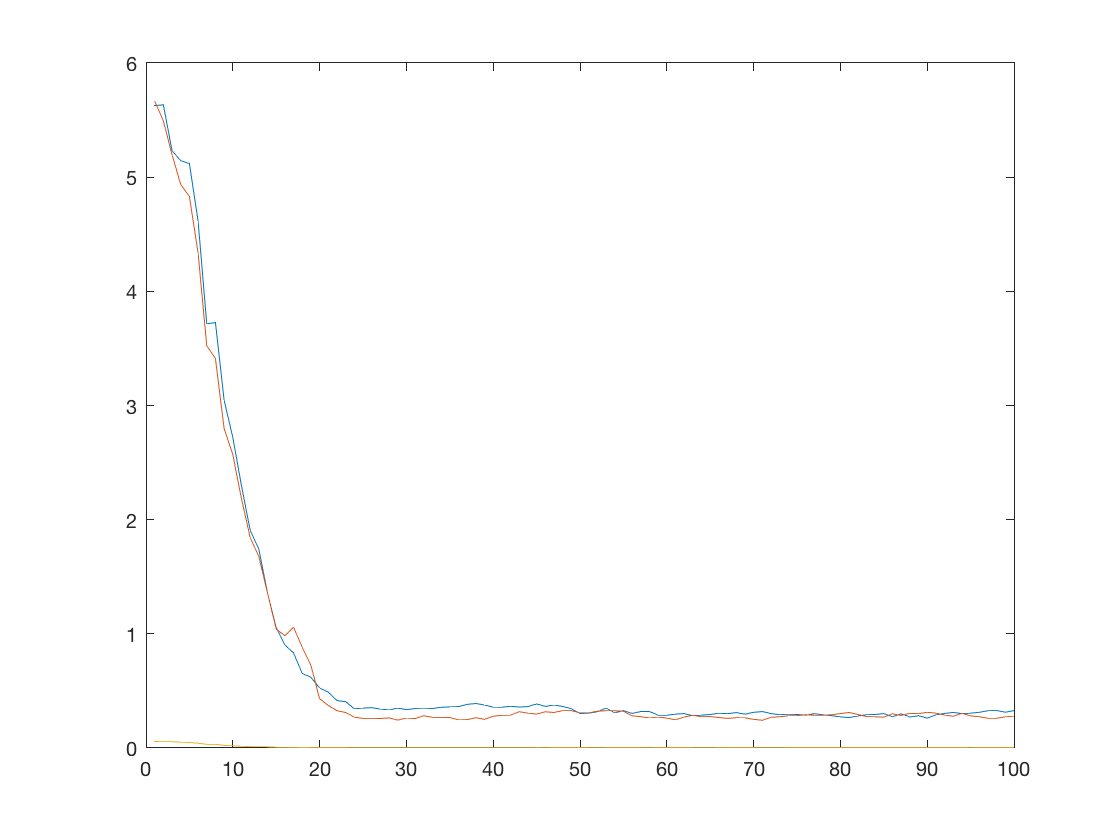


clf
plot(pf.std(1:100,:))

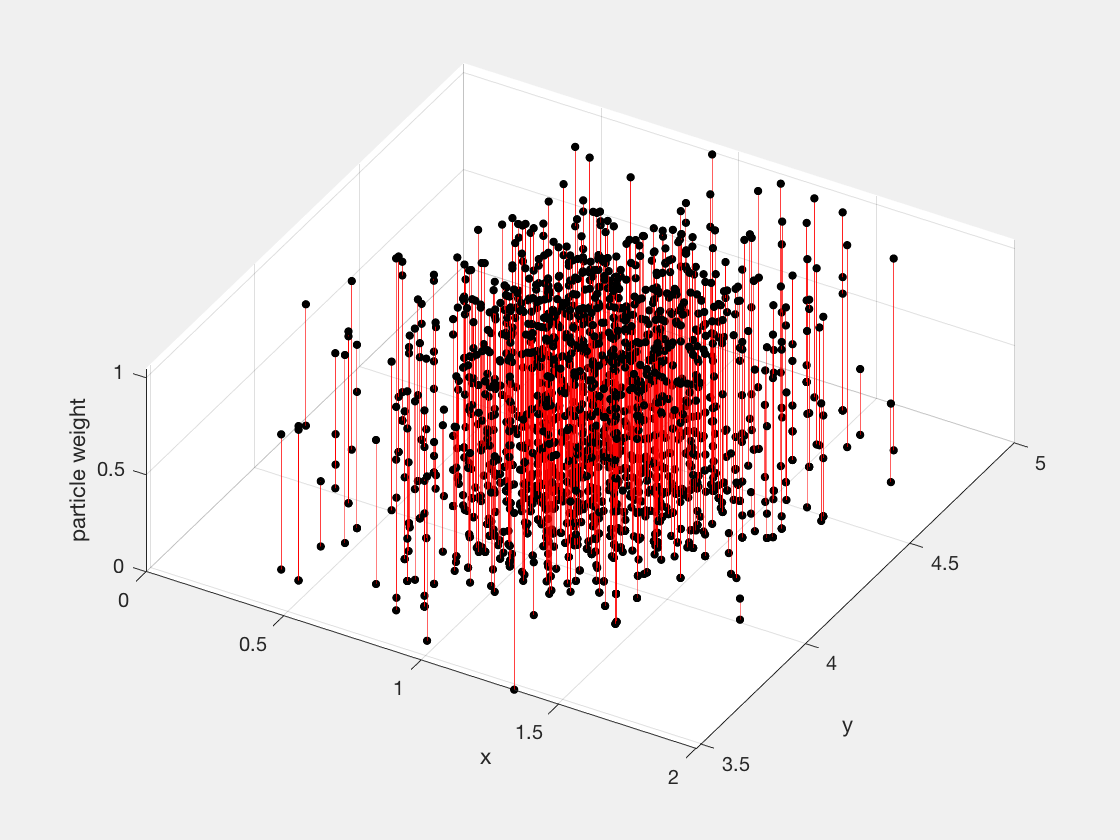


clf
pf.plot_pdf()

## 6.8  Application: Scanning laser rangefinder

## Laser odometry

pg = PoseGraph('killian.g2o', 'laser');

loaded g2o format file: 3873 nodes, 4987 edges in 2.05 sec
  3873 laser scans: 180 beams, fov -90 to 90 deg, max range 50



[r, theta] = pg.scan(2580);
about r theta

r [double] : 1x180 (1.4 kB)
theta [double] : 1x180 (1.4 kB)


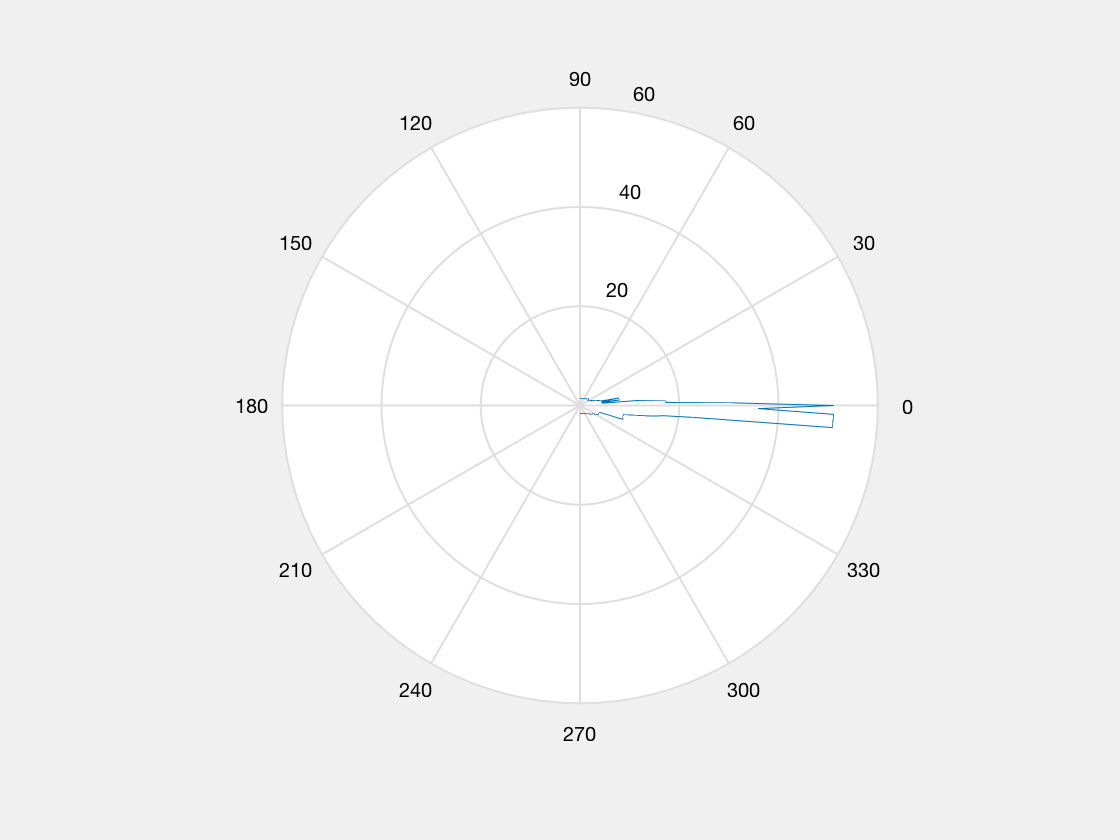


clf
polar(theta, r)

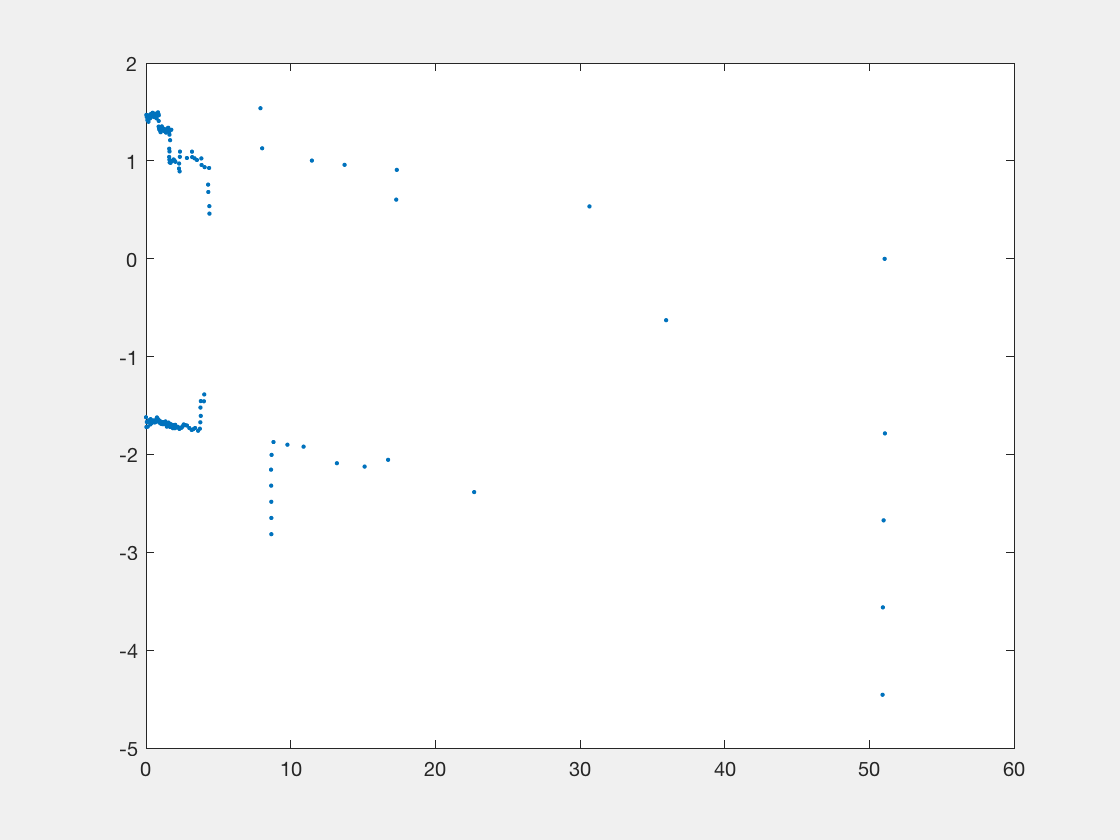


[x,y] = pol2cart (theta, r);
plot (x, y, '.')


p2580 = pg.scanxy(2580);
p2581 = pg.scanxy(2581);
about p2580

p2580 [double] : 2x180 (2.9 kB)



T = icp( p2581, p2580, 'verbose' , 'T0', transl2(0.5, 0), 'distthresh', 3)

[1]: n=132/180, d=   0.466, t = (   0.499   -0.006), th = (  -0.0) deg
[2]: n=130/180, d=   0.429, t = (   0.500   -0.009), th = (   0.0) deg
[3]: n=130/180, d=   0.427, t = (   0.501   -0.011), th = (   0.0) deg
[4]: n=130/180, d=   0.426, t = (   0.502   -0.012), th = (   0.0) deg
[5]: n=130/180, d=   0.425, t = (   0.503   -0.011), th = (   0.0) deg
[6]: n=130/180, d=   0.425, t = (   0.503   -0.011), th = (   0.0) deg
terminate on minimal change of error norm

T =     1.0000   -0.0002    0.5032
    0.0002    1.0000   -0.0113
         0         0    1.0000



pg.time(2581)-pg.time(2580)

ans = 1.7600

## Laser-based map building

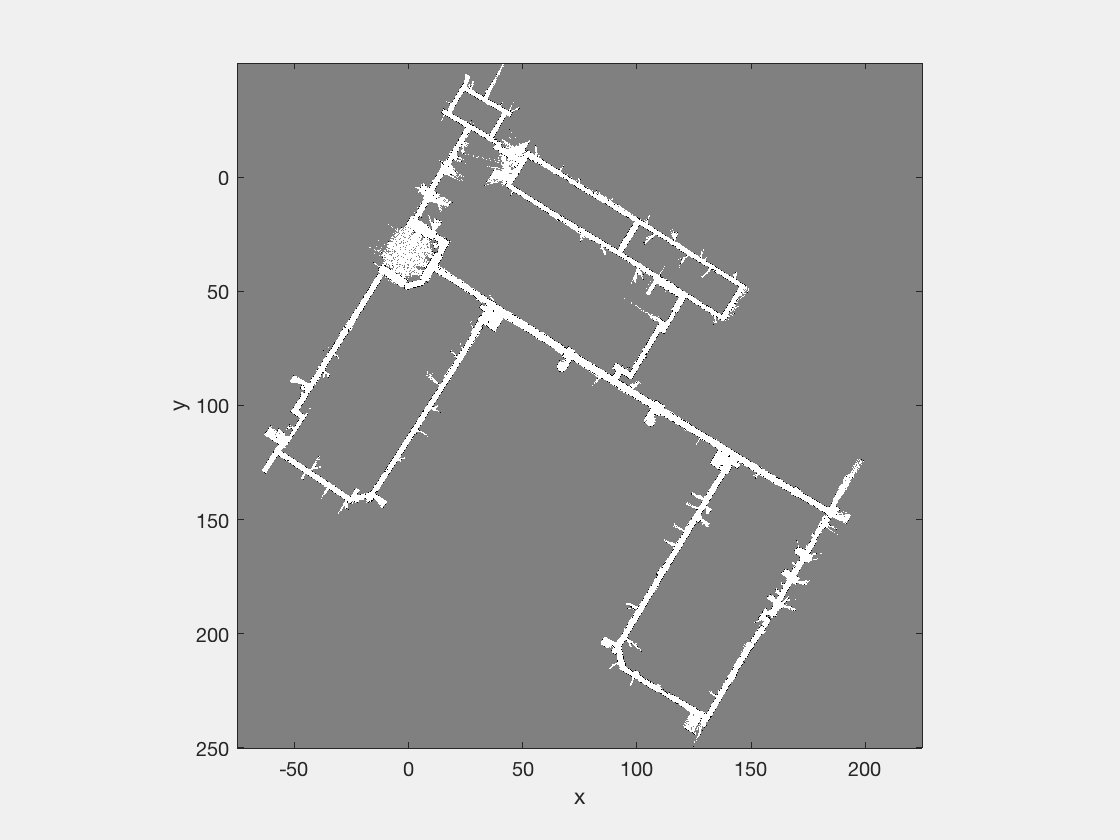

map = pg.scanmap();
pg.plot_occgrid(map)